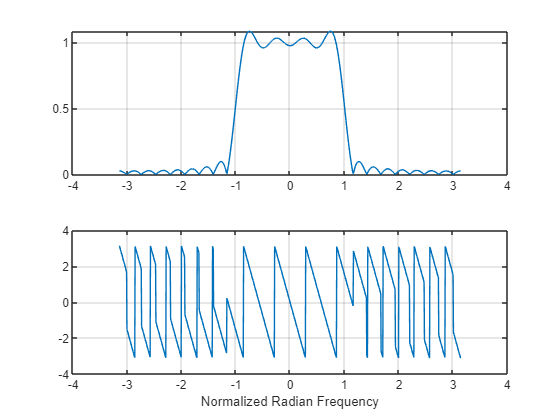

% Section 1.3

M = 22; %-- Filter Order is even
n = 0:M; %-- "n index" vector
%%nsh = n.*n - M/2; %-- put main lobe in center of h[n]
nsh = n - M/2; %-- put main lobe in center of h[n]
wb = 0.32*pi; %-- "Bandwidth" parameter of sinc
bb = sin(wb*nsh)./(pi*nsh); %-- Filter Coefficients
bb(find(nsh==0)) = wb/pi; %-- fix the divide by zero
ww = -pi:(pi/500):pi; %-- omega hat frequency vector
H = freqz(bb, 1, ww); %<--freekz(bb,1,ww) is an alternative
subplot(2,1,1);
plot(ww, abs(H)), grid on
subplot(2,1,2);

figure(1)
plot(ww, angle(H)), grid on
xlabel('Normalized Radian Frequency')

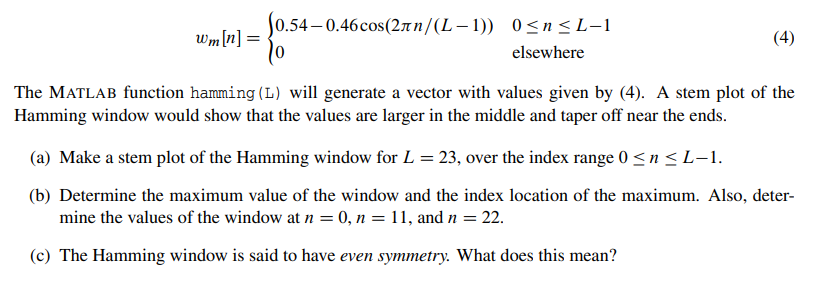

%Section 1.4: 

%part a: 
L = 23

L = 23

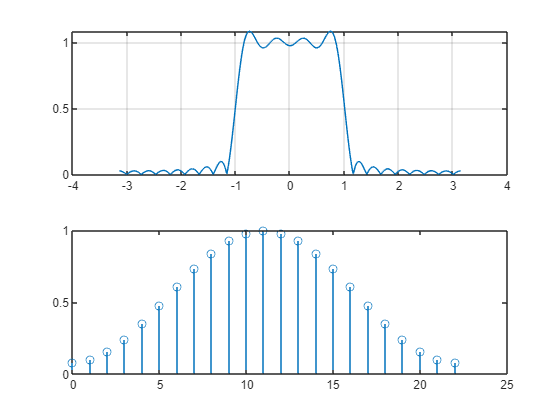

Hamming_window = hamming(L);
n = linspace(0,L-1,L);

figure(2)
stem(n,Hamming_window)


%part b: 
[maxVal, maxIndex]= max(Hamming_window)

maxVal = 1

maxIndex = 12

val_n0 = Hamming_window(1)

val_n0 = 0.0800

val_n11 = Hamming_window(11)

val_n11 = 0.9814

val_n22 = Hamming_window(22)

val_n22 = 0.0986


%part c: The hamming window is symmetric about a given axis, making it an
%even function. This is because the shape of the hamming window, as seen in
%the top figure; notice the symmetry around x=0. 

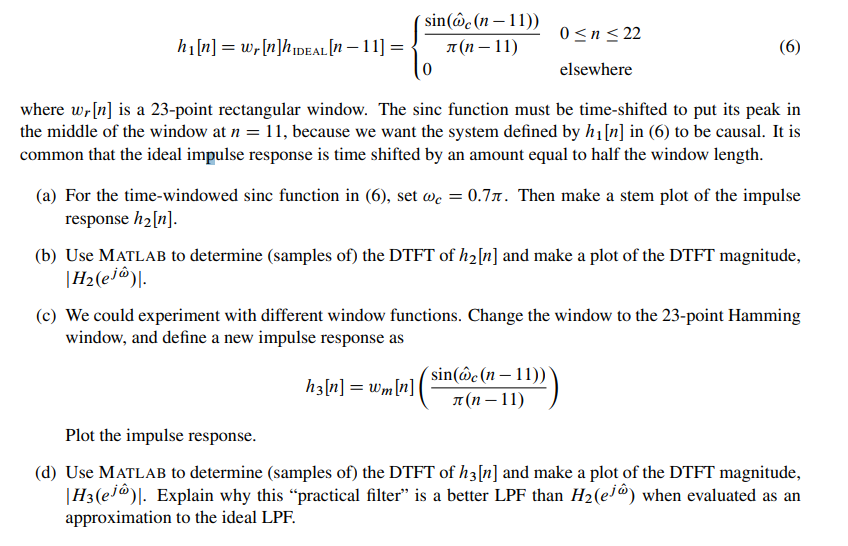

%1.5.1 Truncate the Ideal Impulse Response

%part a:
n = linspace(0,L-1,L);
h2 = zeros(1,length(n));
wc = 0.7*pi

wc = 2.1991

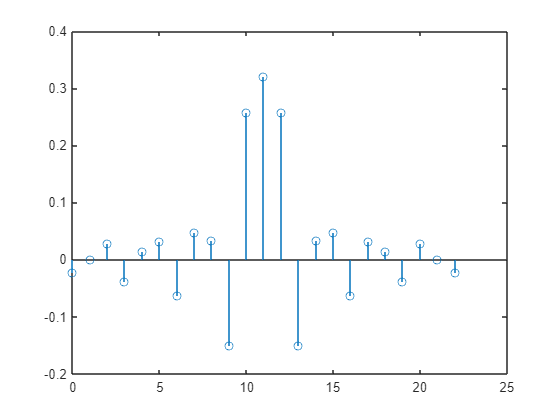

nsh = n-11;
h2 = sin(wc.*(nsh))./(pi.*(nsh));
h2(find(nsh==0)) = wb/pi; %-- fix the divide by zero
% for i=1:length(n)
%     %bb(find(nsh==0)) = wb/pi; %-- fix the divide by zero
%     if n(i) == 0
%         h2(i) = wc/pi;
%     else
%         h2(i) = sin(wc*(n(i)-11))/(pi*(n(i)-11));
%     end
% end
figure(3)
stem(n,h2)

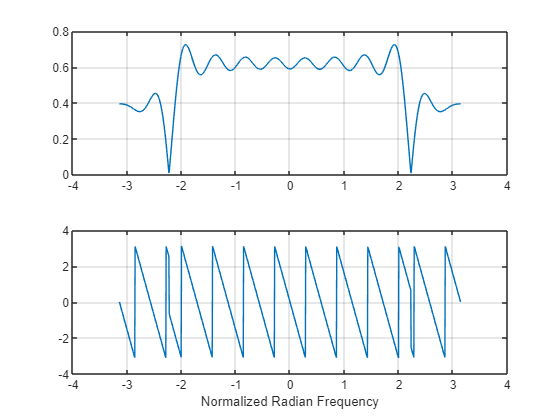


%partb: INSEWRT SUBPLOTSS 
%w = linspace(-pi,pi,length(n));
ww = -pi:(pi/500):pi; %-- omega hat frequency vector

H2 = freqz(h2, 1, ww); %<--freekz(bb,1,ww) is an alternative
figure(4)
subplot(2,1,1);
plot(ww, abs(H2)), grid on

subplot(2,1,2);
plot(ww, angle(H2)), grid on
xlabel('Normalized Radian Frequency')

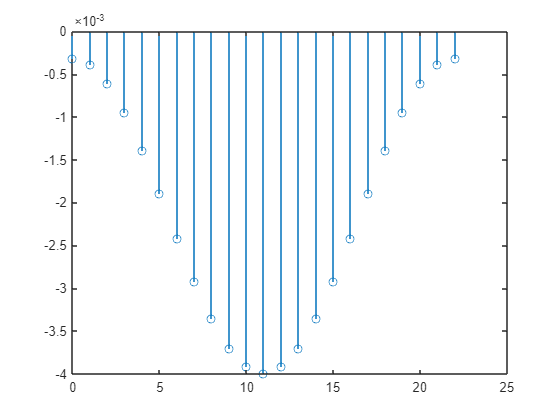


%partc: 
L = 23;
Hamming_window = hamming(L);
h3 = zeros(1,length(n));

nsh = n -11;
h3 = Hamming_window.*sin(wc*(nsh))/(pi.*(nsh));
% for i=1:length(n)
%     if n(i) == 0
%         h3(i) = wc/pi;
%     else
%         h3(i) = Hamming_window(i)*sin(wc*(n(i)-11))/(pi*(n(i)-11));
%     end
% end
figure(5)
stem(n,h3)




%part d: 
%w = linspace(-pi,pi,length(n));
ww = -pi:(pi/500):pi; %-- omega hat frequency vector
H3 = freqz(h3, 1, ww)

H3 =   -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0001i  -0.0003 + 0.0001i  -0.0003 + 0.0001i  -0.0003 + 0.0001i  -0.0002 + 0.0001i  -0.0002 + 0.0001i  -0.0002 + 0.0001i  -0.0002 + 0.0002i  -0.0002 + 0.0002i  -0.0001 + 0.0002i  -0.0001 + 0.0001i  -0.0001 + 0.0001i  -0.0001 + 0.0001i  -0.0001 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0001i  -0.0000 - 0.0001i  -0.0000 - 0.0001i  -0.0000 - 0.0001i  -0.0001 - 0.0001i  -0.0001 - 0.0002i  -0.0001 - 0.0002i  -0.0001 - 0.0002i  -0.0002 - 0.0002i  -0.0002 - 0.0002i  -0.0002 - 0.0002i  -0.0002 - 0.0002i  -0.0002 - 0.0002i  -0.0003 - 0.0001i  -0.0003 - 0.0001i  -0.0003 - 0.0001i  -0.0003 - 0.0001i  -0.0003 - 0.0001i  -0.0003 - 0.0001i  -0.0003 - 0.0000i  -0.0003 - 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0001i  -0.0003 + 0.0001i


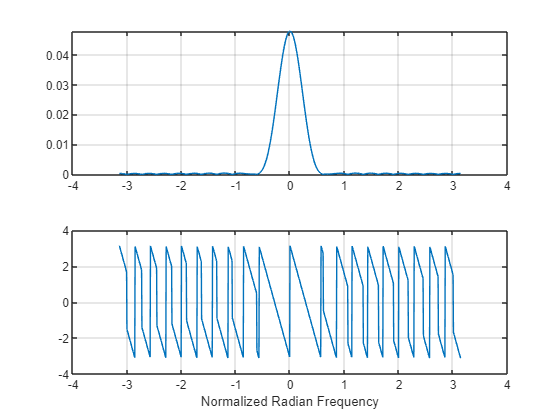

figure(6)
subplot(2,1,1);
plot(ww, abs(H3)), grid on

subplot(2,1,2);
plot(ww, angle(H3)), grid on
xlabel('Normalized Radian Frequency')


%%%%%%%%%%%%%%%%%%%%%!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
%Finish the explanation! 
%%%%%%%%%%%%%%%%%%%%%!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!

% Section 1.6 
%The filter coefficients can be “exported” from the GUI by using the menu File->Export Coeffs. To
%have some filters for comparison, redo the designs from the Section 1.5.1, and export the filter coefficients
%to the workspace under unique names. Then you can make your own plot of the frequency response in
%MATLAB using the freekz function (or freqz) followed by a plot command.


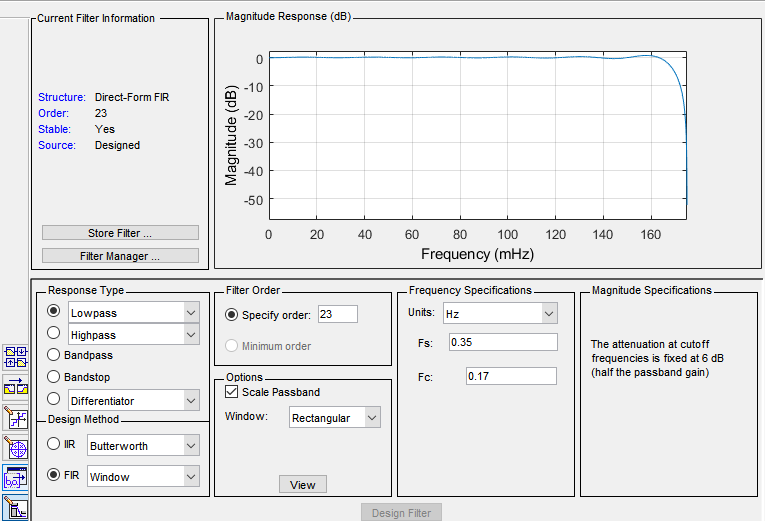

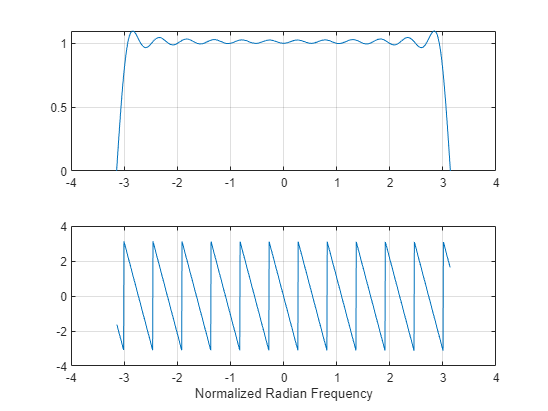

GUIfilter_rect_coef = [-0.0143765566056423	0.0180447146203763	-0.0223245377923143	0.0274104877704686	-0.0336025721949859	0.0413877424193683	-0.0516100666378250	0.0658677712851804	-0.0875908847191827	0.125705166478773	-0.212951650439407	0.644040385815190	0.644040385815190	-0.212951650439407	0.125705166478773	-0.0875908847191827	0.0658677712851804	-0.0516100666378250	0.0413877424193683	-0.0336025721949859	0.0274104877704686	-0.0223245377923143	0.0180447146203763	-0.0143765566056423];
ww = -pi:(pi/500):pi; %-- omega hat frequency vector
H2_filterDesign= freqz(GUIfilter_rect_coef, 1, ww);
figure(6)
subplot(2,1,1);
plot(ww, abs(H2_filterDesign)), grid on

subplot(2,1,2);
plot(ww, angle(H2_filterDesign)), grid on
xlabel('Normalized Radian Frequency')

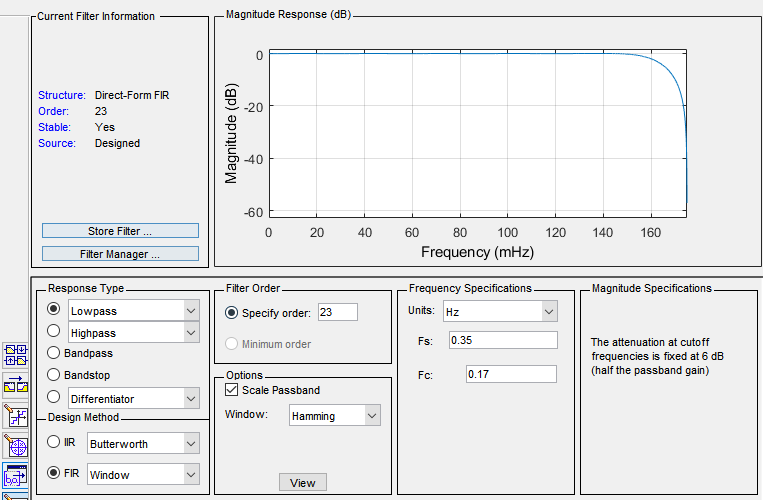

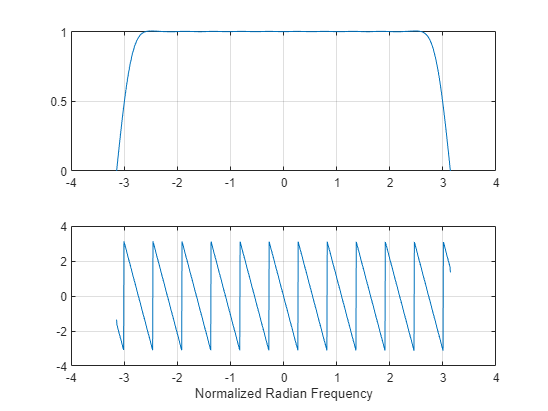

GUIfilter_hamming_coef = [-0.00113688299325278	0.00173122085090907	-0.00324319773291939	0.00612414141687301	-0.0109070425989879	0.0182631961719097	-0.0291500367962164	0.0451888475954350	-0.0697224961754959	0.111437869439427	-0.202483483787238	0.633897864609557	0.633897864609557	-0.202483483787238	0.111437869439427	-0.0697224961754959	0.0451888475954350	-0.0291500367962164	0.0182631961719097	-0.0109070425989879	0.00612414141687301	-0.00324319773291939	0.00173122085090907	-0.00113688299325278];
ww = -pi:(pi/500):pi; 
H3_filterDesign= freqz(GUIfilter_hamming_coef, 1, ww);
figure(6)
subplot(2,1,1);
plot(ww, abs(H3_filterDesign)), grid on

subplot(2,1,2);
plot(ww, angle(H3_filterDesign)), grid on
xlabel('Normalized Radian Frequency')

%section 1.7.l1 Passband defined for the frequency response. 

%part a_:

